# Lecture 12: Image Thresholding

# Part 2: Variable (Adaptive) Thresholding

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture12 - Image Thresholding

- pdf versions of the .mlx files are also available for those using GNU Octave

clearvars; close all; clc;

## Non-uniform illumination examples

- Use circles.tif or illum.png images

- First check the results of global thresholding for the sample images

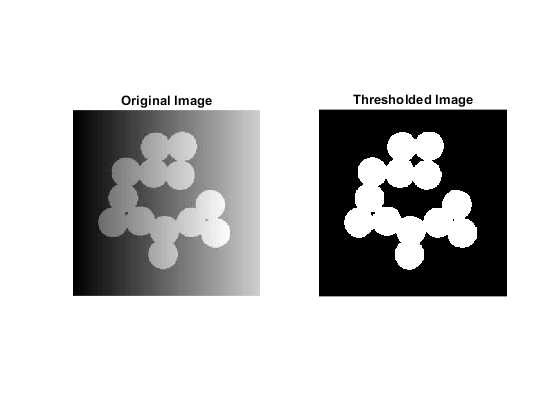

% read input image
I = imread('images/circles.tif');
if(size(I,3) == 3) % convert to grayscale if needed
    I=rgb2gray(I); 
end

% define an anonymous function
fun = @(block_struct) imbinarize(block_struct.data);

s = [floor(size(I,1)),floor(size(I,2)/4)]; % determine the size of the blocks
Iout = blockproc(I,s,fun); % apply fun to each block

% plot images
subplot(1,2,1), imshow(I), title('Original Image');
subplot(1,2,2), imshow(Iout), title('Thresholded Image');

## Adaptive thresholding using local image properties

- Use printedtext.png and printedtex2.png images

- First check the results of global thresholding for the sample images

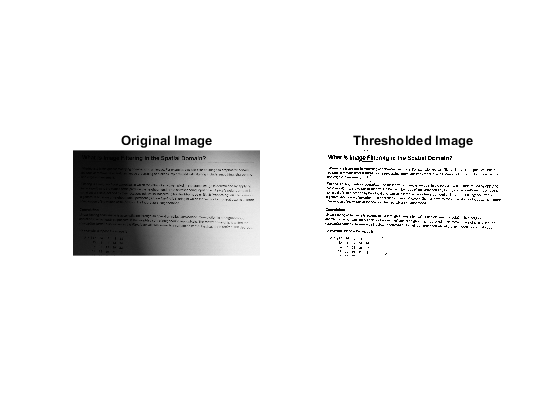

% read input image
I2 = imread('images/printedtext.png');
if(size(I2,3) == 3) % convert to grayscale if needed
    I2=rgb2gray(I2); 
end

% adaptively threshold the image
T = adaptthresh(I2, 0.4, 'ForegroundPolarity', 'dark');
BW = imbinarize(I2, T);

% or you can directly use imbinarize function with adaptive option
%BW = imbinarize(I2, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.4);

% plot images
figure, subplot(1,2,1), imshow(I2), title('Original Image'); 
subplot(1,2,2), imshow(BW), title('Thresholded Image');